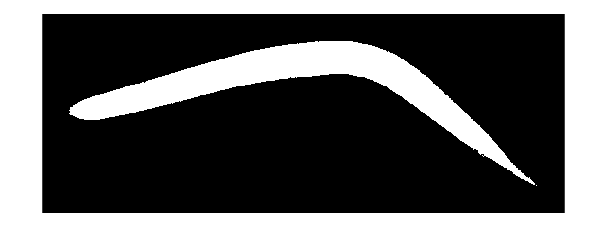



[BW_ini_regio_cropped, BB_values, proporcio_img_new] = retallar_BWimatge_BB_2(BW_final, 4);
imshow(BW_ini_regio_cropped)


imshow(imcrop(BW_final, proporcio_img_new))

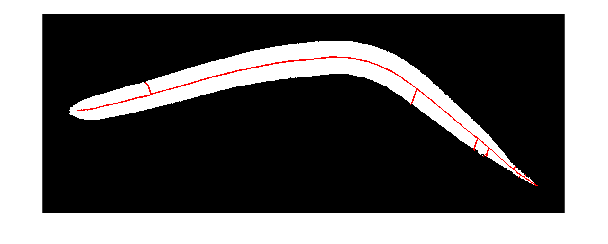



[BW_skel_raw, dades_imatge_row, dades_imatge_manual_corrected] = esqueletonitzacio_josep_optim_2(BW_ini_regio_cropped, 1.14, false, false, 5);

% imshow(BW_skel_raw)
imshow(imoverlay(BW_ini_regio_cropped, eixamplar_imgBW(BW_skel_raw, 1), "r"))

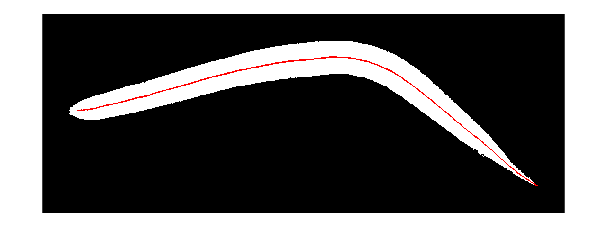


% Reduce line
[BW_skel_2, dades_imatge_row, dades_imatge_manual_corrected] = esqueletonitzacio_josep_optim_2(BW_ini_regio_cropped, 1.14, false, true, 5);
% imshow(BW_skel_2)
imshow(imoverlay(BW_ini_regio_cropped, eixamplar_imgBW(BW_skel_2, 1), "r"))

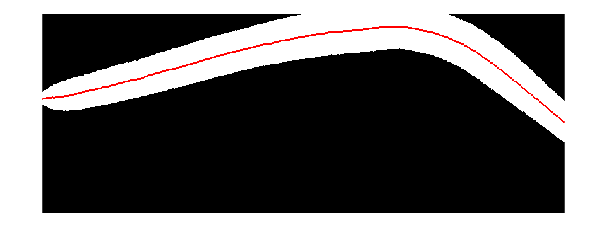


% Extend skel
[BW_skel_3, dades_imatge_row, dades_imatge_manual_corrected] = esqueletonitzacio_josep_optim_2(BW_ini_regio_cropped, 1.14, true, true, 5);
% imshow(BW_skel_3)
imshow(imoverlay(BW_ini_regio_cropped, eixamplar_imgBW(BW_skel_3, 1), "r"))

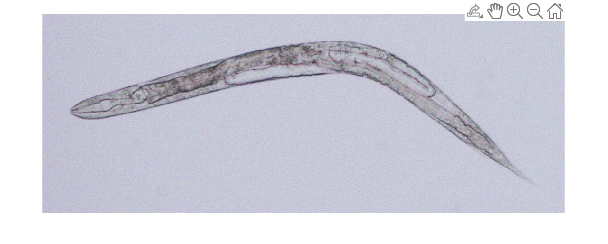


imageArray_croped = imcrop(imageArray, proporcio_img_new);
imshow(imageArray_croped)